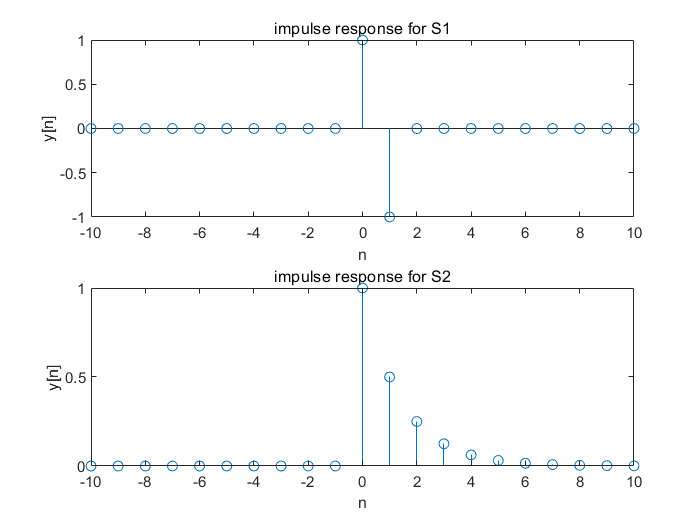

clc;clear;close all;
n=-10:1:10;
omega_n=(n==0);

figure(1)
subplot(2,1,1)
s1=lab2_4_f1(omega_n);
stem(n,s1),xlabel('n'),ylabel('y[n]'),title('impulse response for S1');
subplot(2,1,2)
s2=lab2_4_f2(omega_n);
stem(n,s2),xlabel('n'),ylabel('y[n]'),title('impulse response for S2');

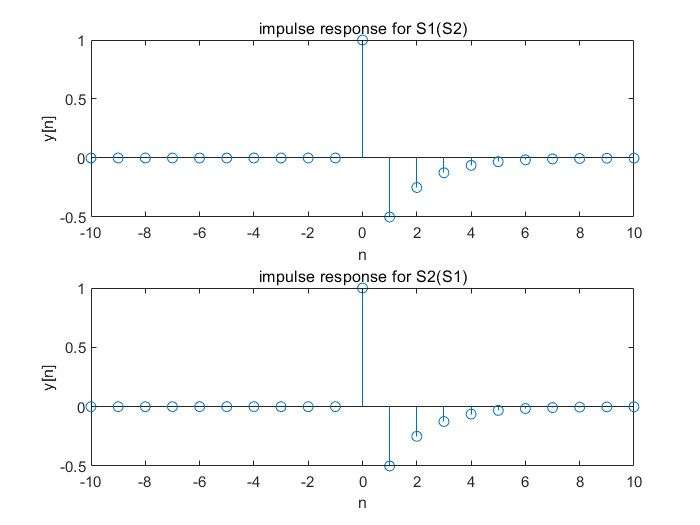

figure(3)
subplot(2,1,1)
s3=lab2_4_f1(lab2_4_f2(omega_n));
stem(n,s3),xlabel('n'),ylabel('y[n]'),title('impulse response for S1(S2)');
subplot(2,1,2)
s4=lab2_4_f2(lab2_4_f1(omega_n));
stem(n,s4),xlabel('n'),ylabel('y[n]'),title('impulse response for S2(S1)');

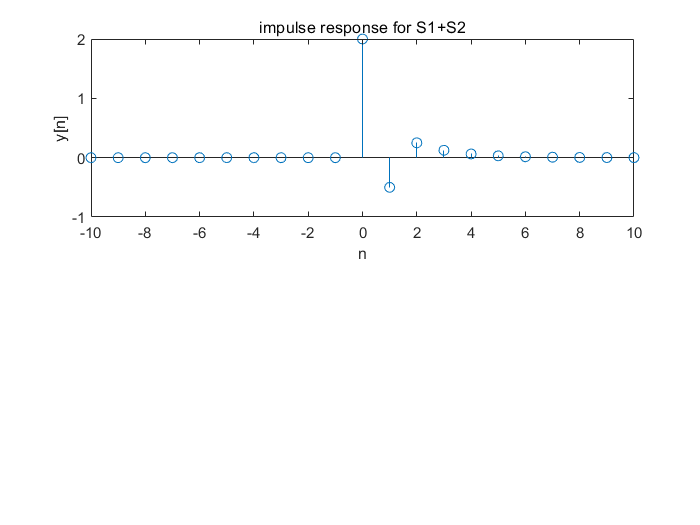

figure(5)
subplot(2,1,1)
s5=lab2_4_f2(omega_n)+lab2_4_f1(omega_n);
stem(n,s5),xlabel('n'),ylabel('y[n]'),title('impulse response for S1+S2');

[y,Fs]=audioread("music.au");
y=y';
sound(y,Fs);

s1_out=lab2_4_f1(y);
sound(s1_out,Fs);

s2_out=lab2_4_f2(y);
sound(s2_out,Fs);